# Classify Video Sequences in a Video File

This example shows how to classify video sequences in a video file using a SlowFast Video Classifier pretrained on the Kinetics-400 video activity recognition dataset. To learn more about how to train a video classifier network for your dataset, see [Gesture Recognition Using Deep Learning](docid:vision_ug#mw_0719784f-1579-40e5-ae7b-f8be8615cbd8). 

### Load SlowFast Video Classifier

trainedmodel = load("G:\FYP\r2plus1d-V2.mat");
R2D = trainedmodel.data.r2plus1d;

### Setup Video Player and Video Reader

Specify the video file name to stream video frames.

videoFilename = "G:\FYP\Testing_video\figt1.avi";

Create a VideoReader to read video.

reader = VideoReader(videoFilename);

Setup a video player.

player = vision.VideoPlayer;
player.Position(3:4) = [650,480];

### Classify Video Sequences

Specify how frequently the classifier should be applied to incoming video frames. 

classifyInterval = 10;

A value of 10 balances runtime performance against classification performance. Increase this value to improve runtime performance at the cost of missing actions from the video file. 

Obtain the sequence length of the SlowFast Video Classifier. Classify only after capturing at least `sequenceLength` number of frames from the video file.

sequenceLength = R2D.InputSize(4);

Read video frames using the `hasFrame` and `readFrame` functions of the `VideoReader`. Using the `updateSequence` function update the video classifier's sequence. Using the `classifySequence` function classify the updated sequence.

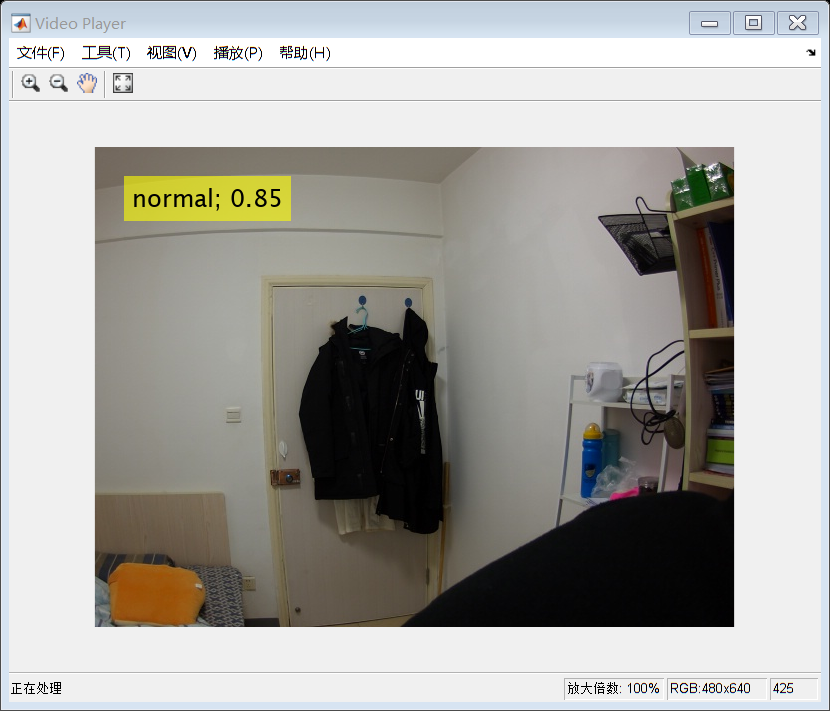

numFrames = 0;
text = "";

while hasFrame(reader)
    frame = readFrame(reader);
    numFrames = numFrames + 1;

    % Update the sequence with the next video frame.
    R2D = updateSequence(R2D,frame);

    % Classify the sequence only at every classifyInterval number of frames.
    if mod(numFrames, classifyInterval) == 0 && numFrames >= sequenceLength
        [label,score] = classifySequence(R2D);
        text = string(label) + "; " + num2str(score, "%0.2f");
    end
    frame = insertText(frame,[30,30],text,'FontSize',24);
    step(player,frame);
    pause(0.03)
end